# Multivariable Linear Regression

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and displays the table variable names.

data = readtable("data\dataMulti.xlsx", Sheet="data");
dataTrain = readtable("data\dataMulti.xlsx", Sheet="dataTrain");
dataTest = readtable("data\dataMulti.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           100x4              4813  table              
  dataTest        30x4              2573  table              
  dataTrain       70x4              3853  table              



data.Properties.VariableNames

ans = 1×4 cell array
    {'X1'}    {'X2'}    {'X3'}    {'Y'}


## Tasks 1 & 2

The table `data` has three predictor variables (`X1`, `X2`, `X3`) and one response (`Y`). It has been split into training and test sets: `dataTrain` and `dataTest`.

You can find a reference for Wilkinson–Rogers notation in the [documentation](https://www.mathworks.com/help/stats/fitlm.html#inputarg_modelspec).

mdl = fitlm(dataTrain, "Y ~ X3 + X1^2")

mdl = Linear regression model:
    Y ~ 1 + X1 + X3 + X1^2

Estimated Coefficients:
                    Estimate         SE          tStat        pValue  
                   __________    __________    _________    __________

    (Intercept)      -0.38043        8.3718    -0.045442        0.9639
    X1              -0.014043     0.0037879      -3.7073    0.00044911
    X3                0.71314      0.081914       8.7059    2.3795e-12
    X1^2           1.1953e-06    5.9868e-07       1.9966      0.050265


Number of observations: 66, Error degrees of freedom: 62
Root Mean Squared Error: 2.85
R-squared: 0.872,  Adjusted R-Squared: 0.866
F-statistic vs. constant model: 141, p-value = 1.18e-27

yPred = predict(mdl, dataTest);

Compare actual and predicted response.

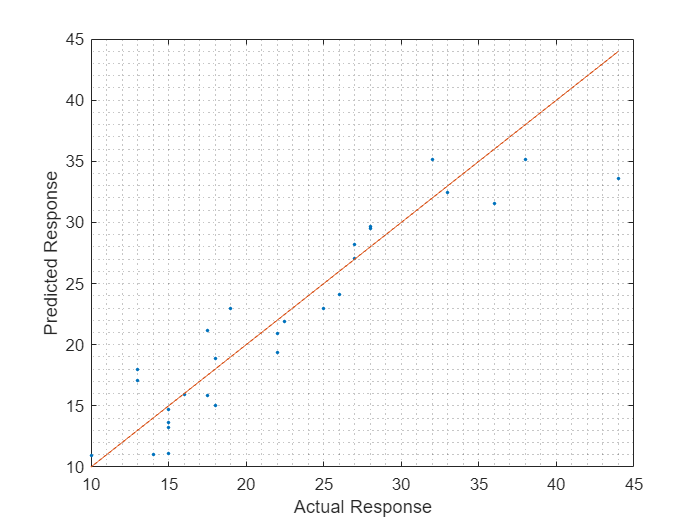

plot(dataTest.Y, yPred, ".")
hold on
plot(dataTest.Y, dataTest.Y)
hold off
grid minor
xlabel("Actual Response")
ylabel("Predicted Response")